依赖[统一实验分析作图v17.1.1](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

启动时间示例

预加载此脚本一次即可

[MOpCoeff,MOpNtats]=TransferLearning.CoeffNtats("MOp");

在2~5s、5~8s、8~12s三段时间各取一个 AB PeakTime 相等且 AB PeakValue 之较小者最大的细胞，标出其达峰时间和启动时间

Data=MOpNtats.NTATS{:,:,["Learned4_cue1_water","Transfer_cue2_water_hit","Transfer_cue2_water_miss"]};
PeakData=table;
PeakData.Data=Data(any(Data,2:3),:,:);
[PeakData.Value,PeakData.Time]=max(PeakData.Data,[],2);
PeakData=PeakData(PeakData.Time(:,:,1)==PeakData.Time(:,:,2),:);
PeakData.MinValue=min(PeakData.Value(:,:,1),PeakData.Value(:,:,2));
PeakData.Time=(PeakData.Time-1)/8-3;
Titles=["Task A","Task B hit","Task B miss"];
Xs=linspace(-3,12,121);
Axes=gobjects(3,3);
YLims=zeros(3,2);
figure;
Layout=tiledlayout(3,3,TileSpacing='tight',Padding='none');

2~5s

Part=PeakData(PeakData.Time(:,:,1)>=2&PeakData.Time(:,:,1)<5,:);
[~,Index]=max(Part.MinValue);
for P=1:3
	Axes(1,P)=nexttile;
	plot(Xs,Part.Data(Index,:,P));
	xline(Part.Time(Index,:,P));
	title(Titles(P));
	YLims(P,:)=ylim;
end
ConsistentYLim=[min(YLims(:,1)),max(YLims(:,2))];
for P=1:3
	ylim(Axes(1,P),ConsistentYLim);
end
Axes(1,2).YAxis.TickValues=[];
Axes(1,3).YAxis.TickValues=[];

5~8s

Part=PeakData(PeakData.Time(:,:,1)>=5&PeakData.Time(:,:,1)<8,:);
[~,Index]=max(Part.MinValue);
for P=1:3
	Axes(2,P)=nexttile;
	plot(Xs,Part.Data(Index,:,P));
	xline(Part.Time(Index,:,P));
	YLims(P,:)=ylim;
end
ConsistentYLim=[min(YLims(:,1)),max(YLims(:,2))];
for P=1:3
	ylim(Axes(2,P),ConsistentYLim);
end
Axes(2,2).YAxis.TickValues=[];
Axes(2,3).YAxis.TickValues=[];

8~12s

Part=PeakData(PeakData.Time(:,:,1)>=8&PeakData.Time(:,:,1)<12,:);
[~,Index]=max(Part.MinValue);
for P=1:3
	Axes(3,P)=nexttile;
	plot(Xs,Part.Data(Index,:,P));
	xline(Part.Time(Index,:,P));
	YLims(P,:)=ylim;
end
ConsistentYLim=[min(YLims(:,1)),max(YLims(:,2))];
for P=1:3
	ylim(Axes(3,P),ConsistentYLim);
end
Axes(3,2).YAxis.TickValues=[];
Axes(3,3).YAxis.TickValues=[];

标识

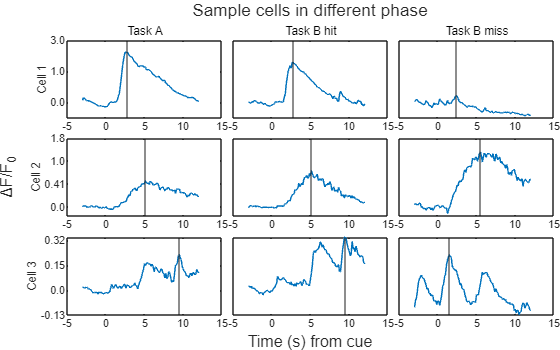

xlabel(Layout,'Time (s) from cue');
ylabel(Layout,'ΔF/F_0');
title(Layout,'Sample cells in different phase');
MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Narrow);
for C=1:3
	ylabel(Axes(C,1),sprintf('Cell %u',C));
	Axes(C,1).YTickLabel=MATLAB.SignificantFixedpoint(2.^str2double(Axes(C,1).YTickLabel)-1,2);
end
print(TransferLearning.ProjectPath('RisingSample.svg'),'-dsvg');